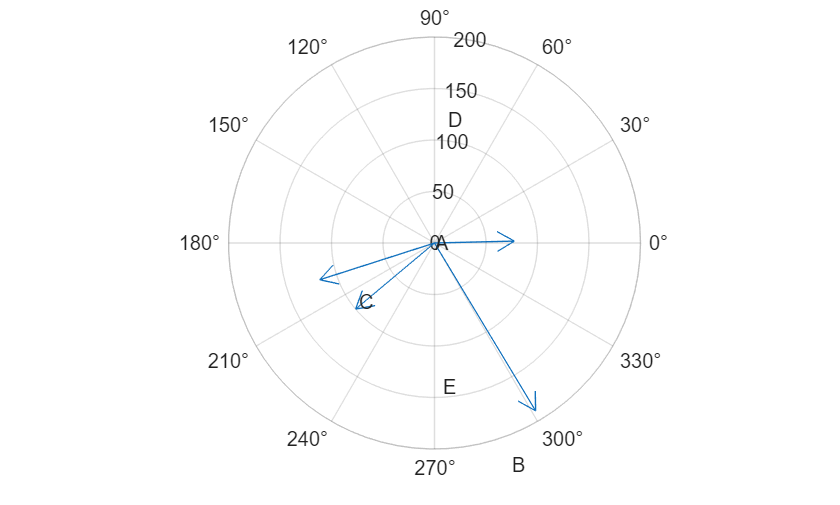

% 如何绘制雷达图
data = [175, 200, 132, 170, 123];
categories = {'A','B','C','D','E'};

theta = linspace(0, 2*pi, length(data)+1);
theta = theta(1:end-1);

% 绘制雷达图
figure;
compassplot(data.*cos(theta), data.*sin(theta));

for i = 1:length(data)
    text(data(i)*1.2*cos(theta(i)), data(i)*1.2*sin(theta(i)), categories{i})
end